# 前処理の実行

計測したデータに対して前処理を行う。

3つの前処理を行った。

- 無音期間の切り出し

- アップサンプリング

- 前後数周期の切り出し

これらの実行処理は"lib/Preprocess.m"クラスに記述してある。

LOAD = true;

if LOAD
    clearvars -except LOAD
else
    clearvars -except data_struct LOAD parameter
end


### **1. データの読み込み**

"data/processed" からデータセットを読み込む。

各計測条件はそれぞれ6回連続して計測されているため、そのうちの一つを選択する。

**1.1 データセットの読み込み**

%config
AMP_TYPE = "a";
SUPPLY_TYPE = "clean";
DATA_PATH  = "./data/processed/";

%読み込み
if LOAD
    data_strct = load(DATA_PATH +"amp_"+AMP_TYPE+"/"+SUPPLY_TYPE+".mat")
    load(DATA_PATH +"amp_"+AMP_TYPE+"/parameter.mat")
end

data_strct = フィールドをもつ struct :
    clean: [1×1 struct]


**1.2 解析データの読み込み**

%config
poly_type = "aa";
freq_type = 3;
vpp_type = 1;
trial_type = 2;
signal_num = 1;

%信号の情報
fs = parameter.Fs

fs = 48000

f = parameter.freq(freq_type)

f = 10000

vpp = parameter.vpp(vpp_type)

vpp = 0.2000

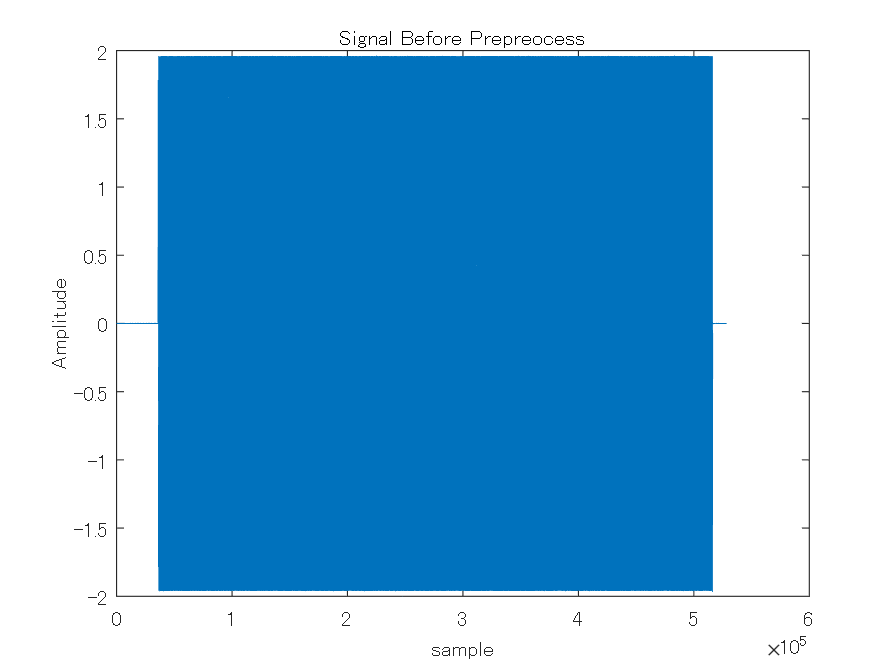


% 前処理クラスをインスタンス化
pre = Preprocess(fs,f);

%%読み込み
data = data_strct.(SUPPLY_TYPE).(poly_type).freq(freq_type).vpp(vpp_type).trial(trial_type).signal;

%６回計測の内一つを抜き出す
signal = data(:,signal_num);

%plot
figure(1)
plot(signal)
ylabel("Amplitude")
xlabel("sample")
title("Signal Before Prepreocess")

### 2.前処理

取得したデータに対して前処理を行う。

**2.1 無音区間の切り抜き**

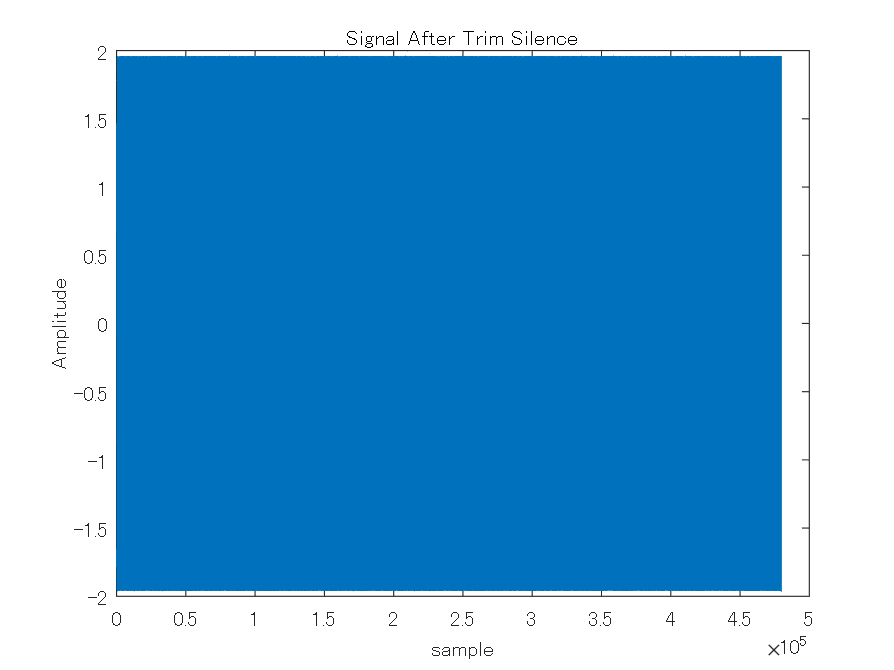

%切り抜き
signal_p1 = pre.trimSilence(signal);

%plot
figure(2)
plot(signal_p1)
ylabel("Amplitude")
xlabel("sample")
title("Signal After Trim Silence")

**2.2 アップサンプリング**

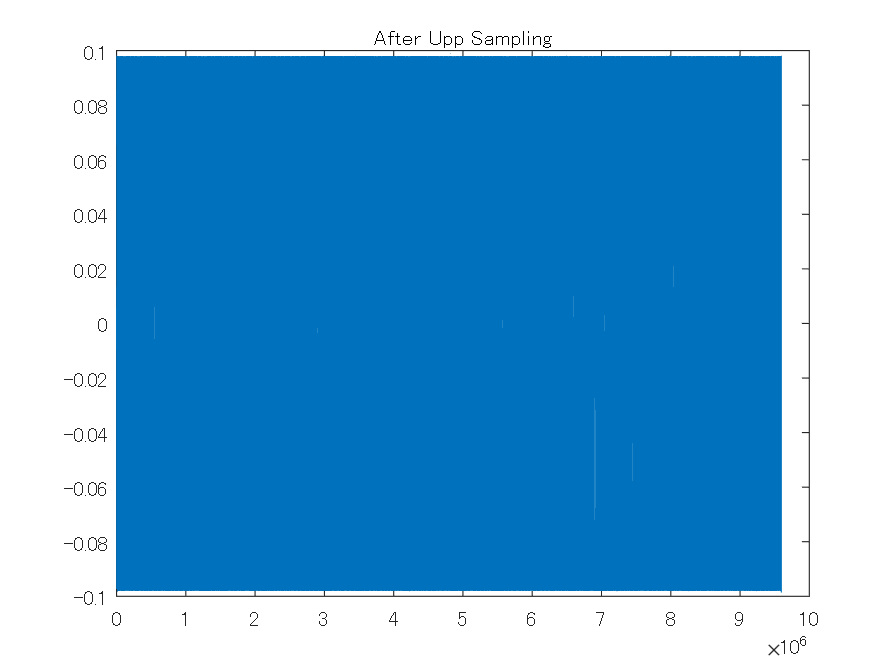

%アップサンプリング
fs_up = 20*fs;
signal_p2 = pre.resampleSignal(fs_up,signal_p1);
fs = fs_up;

%plot
figure(3)
plot(signal_p2)
title("After Upp Sampling")

**2.3前後数周期の切り捨て**

% signal_p2 = signal_p1;
% 切り抜きの周期を指定
rate_trim = 0.05 %rate_time割の周期を前後から切り捨て

rate_trim = 0.0500

trim_period = round(length(signal_p2)*rate_trim / (fs/f))

trim_period = 4998


%切り捨て
pre = pre.resetFs(fs); % サンプリング周波数の再定義
signal_p3 = pre.reshapeSignal(trim_period,signal_p2);

t_end = 0.4998

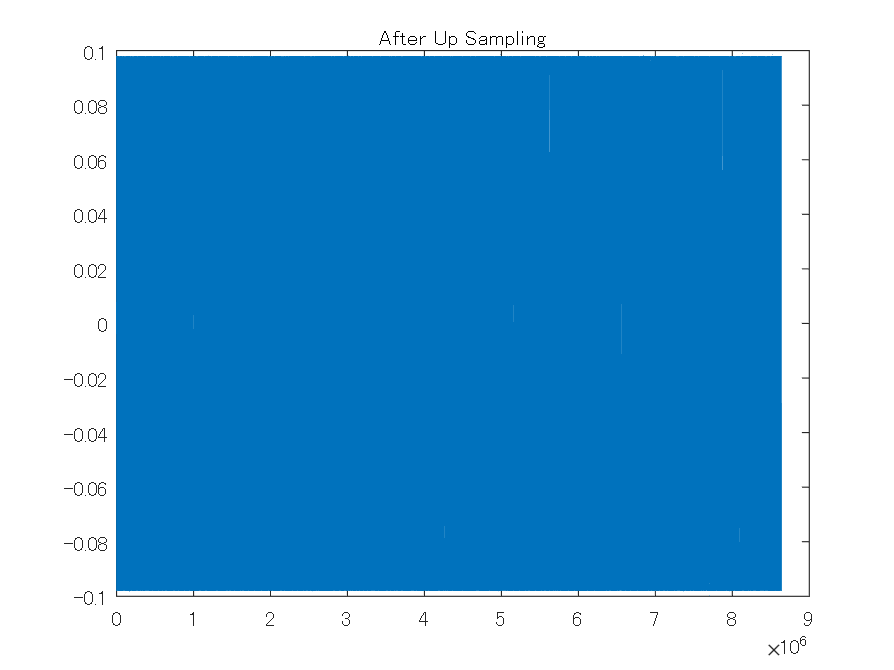


%plot
figure(4)
plot(signal_p3)
title("After Trim Start End")

figure(5)
t = 1:2*fs/f

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


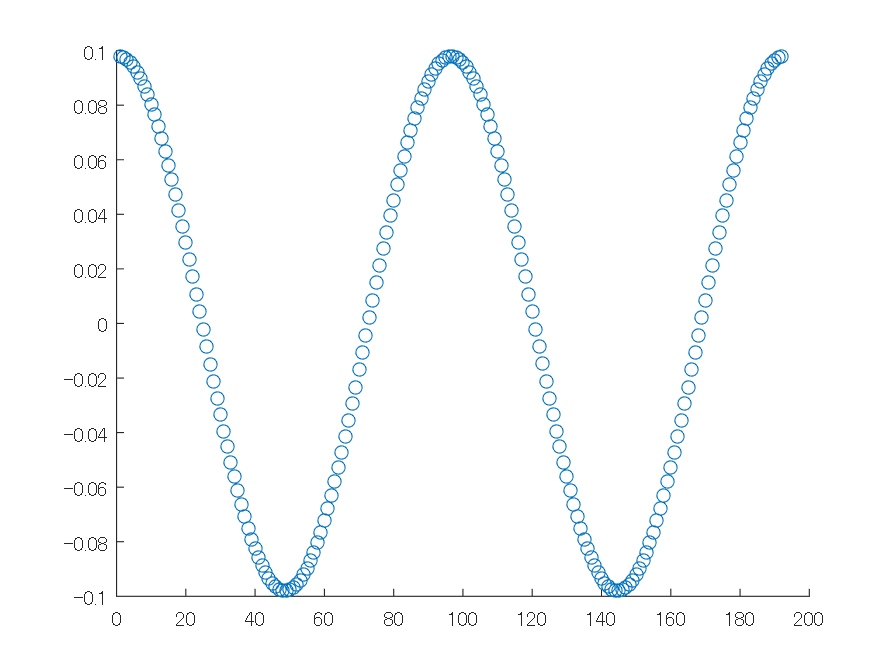

scatter(t,signal_p3(t))

title("Start")

figure(6)
scatter(t,signal_p3(length(signal_p3)-length(t)+1:end))

title("end")
